%the general concept of genetic algorithm (Gen & Cheng 1997, pp.1-2)
% max z= 3*(1-x)^2*exp(-x^2 - (y+1)^2)- 10*(x/5 - x^3 - y^5)*exp(-x^2 -y^2)-1/3*exp(-(x+1)^2 - y^2);
% roulette wheel selection, one cut point crossover, one gene exchange mutation
clear all
close all
clc

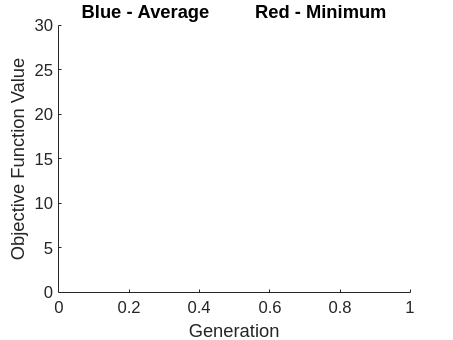

%--------------------------------------------------------------------------
p=20; % Population size
c=5; % number of pairs of chromosomes to be crossovered
m=4; % number chromosomes to be mutated
tg=50; % Total number of generations 
size=4;
%--------------------------------------------------------------------------
figure
title('Blue - Average         Red - Minimum');
xlabel('Generation')
ylabel('Objective Function Value')
ylim([0,30]);
hold on

% Genetic algorithm starts with an initial set of random solutions called population (encoded in a certain way).
P=population(size,p)

P =      3     4     2     1
     3     4     1     2
     3     4     1     2
     4     3     2     1
     1     2     4     3
     2     1     4     3
     4     1     2     3
     3     1     2     4
     1     4     3     2
     3     2     1     4


K=0;
P1 = 0;


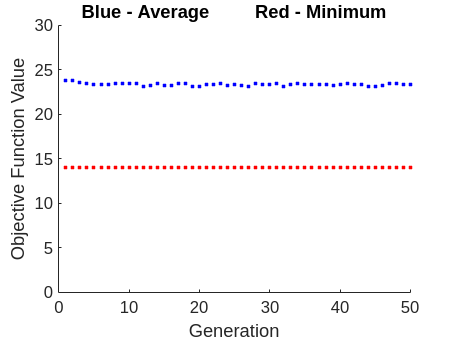

% Each individual in the population is called a chromosome representing a solution to the problem at hand.
% The chromosomes evolve through successive iterations, called generations.
% During each generation, the chromosomes are evaluated using some measures of fitness.

for i=1:tg   
    
    % To create the next generation, new chromosome, called offspring, 
    % are formed by either (a) merging two chromosomes from current 
    % generation using a crossover operator or (b) modifying a chromosome 
    % using a mutation operator.
    
    Cr=crossover(P,c);  % one cut point crossover
    Mu=mutation(P,m);   % one gene exchange mutation
    P(p+1:p+2*c,:)=Cr;
    P(p+2*c+1:p+2*c+m,:)=Mu;
    E=evaluation(P);
    [P S]=selection(P,E);   % roulette wheel selection
    K(i,1)=sum(S)/p;
    K(i,2)=S(1); % best
    plot(K(:,1),'b.'); drawnow
    hold on
    plot(K(:,2),'r.'); drawnow
end

Max_fitness_value=max(K(:,2))

Max_fitness_value = 14

P2 = P(1,:); 

% Best chromosome convert binary to real numbers

Optimal_solution= P2

Optimal_solution =      4     3     2     1
